ans = "Signal 3: 21:12 Actual moment over Rolls [Nm]"

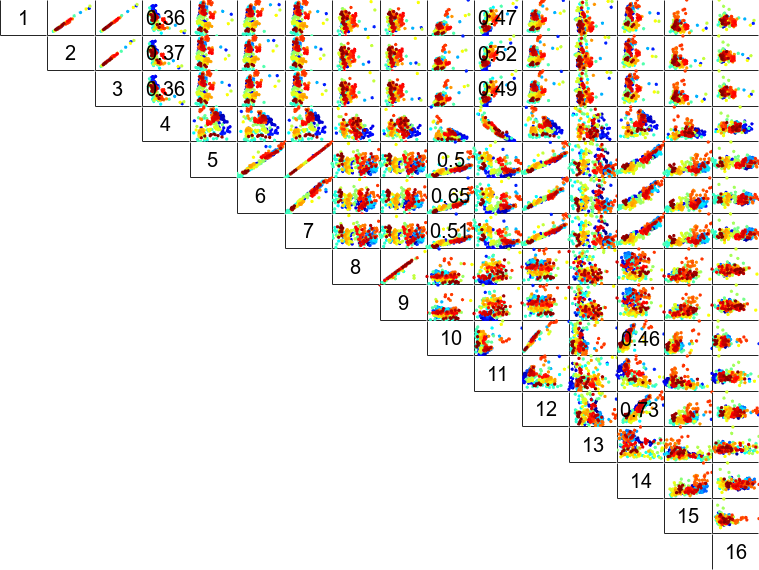

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedSignal = 3; %21:12 Actual moment over Rolls (Nm)
saveFigures = true;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

1.00  0.99  1.00  0.36  0.00  0.04  0.00  0.03  0.01  0.25  0.47  0.08  0.02  0.00  0.00  0.00
0.00  1.00  0.99  0.37  0.01  0.01  0.01  0.03  0.01  0.16  0.52  0.03  0.03  0.01  0.01  0.00
0.00  0.00  1.00  0.36  0.00  0.03  0.00  0.03  0.01  0.21  0.49  0.06  0.03  0.00  0.00  0.00
0.00  0.00  0.00  1.00  0.10  0.03  0.09  0.06  0.02  0.05  0.87  0.00  0.06  0.12  0.02  0.00
0.00  0.00  0.00  0.00  1.00  0.95  1.00  0.02  0.01  0.50  0.26  0.82  0.07  0.86  0.25  0.00
0.00  0.00  0.00  0.00  0.00  1.00  0.95  0.01  0.01  0.65  0.12  0.91  0.05  0.83  0.24  0.00
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.02  0.01  0.51  0.25  0.83  0.06  0.87  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.88  0.00  0.06  0.00  0.03  0.01  0.09  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.00  0.02  0.00  0.12  0.00  0.11  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.00  0.87  0.00  0.46  0.20  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures( ...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     1     4    11
     1     4    11


fig = figure(); hold on;
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

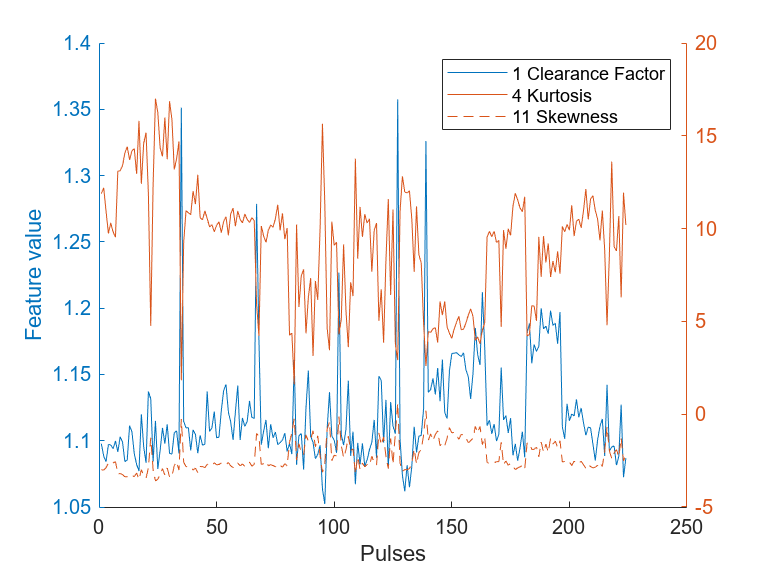

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2 3];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
lgnd = legend(legendAxis, leg); 
set(lgnd,'color','none');
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')    
    %export_fig(filename, '-eps', '-depsc');
end

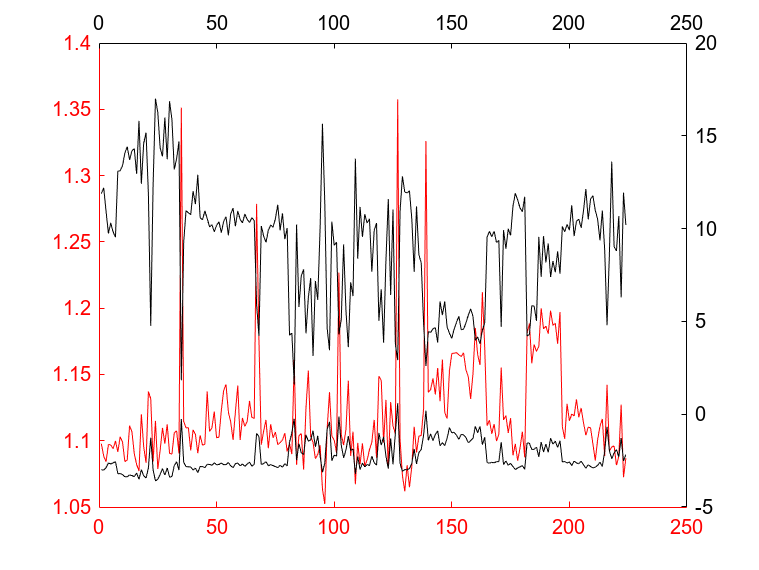

figure(); hold on;
x1 = selectedFeatureData{1};
x2 = selectedFeatureData{2};
x3 = selectedFeatureData{3};
t = 1:numOfPulses;
hl1 = line(t,x1,'Color','r');
ax1 = gca;
set(ax1,'XColor','r','YColor','r')
ax2 = axes('XAxisLocation','top',...
         'YAxisLocation','right',...
         'Color','none',...
         'XColor','k','YColor','k');
hl2 = line(t,x2,'Parent', ax2, 'Color','k');
hl3 = line(t,x3,'Parent', ax2, 'Color','k');

xx = (1:numOfPulses)';
plotyyy(xx, selectedFeatureData{1}, xx, selectedFeatureData{2}, xx, selectedFeatureData{3}, leg);
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

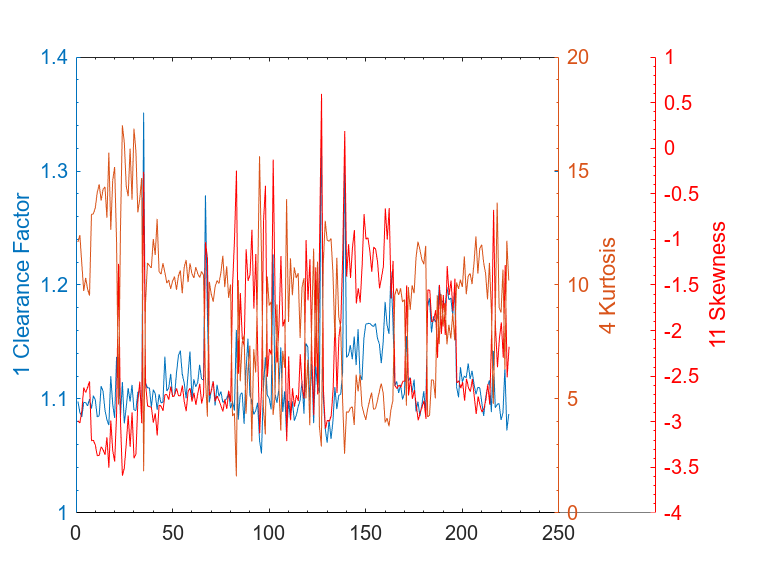

xlabel("Pulses");

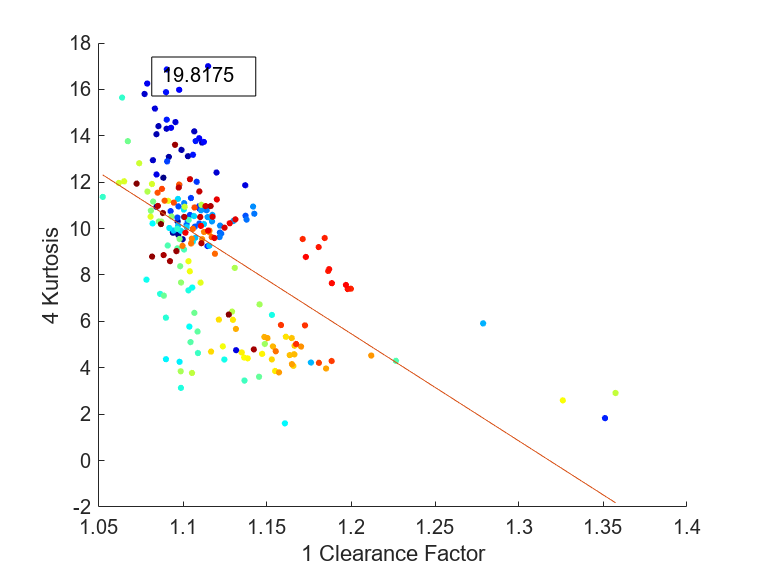

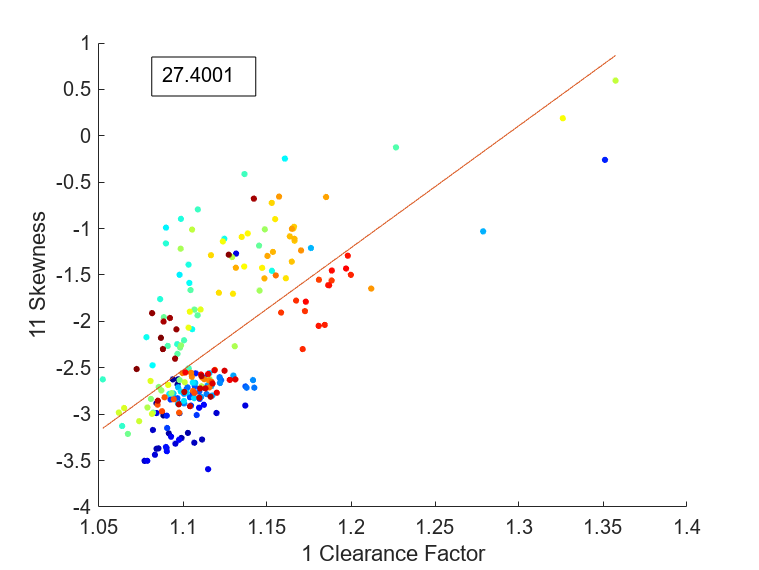

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

txtTitle = "21:12 Actual moment over Rolls [Nm]"

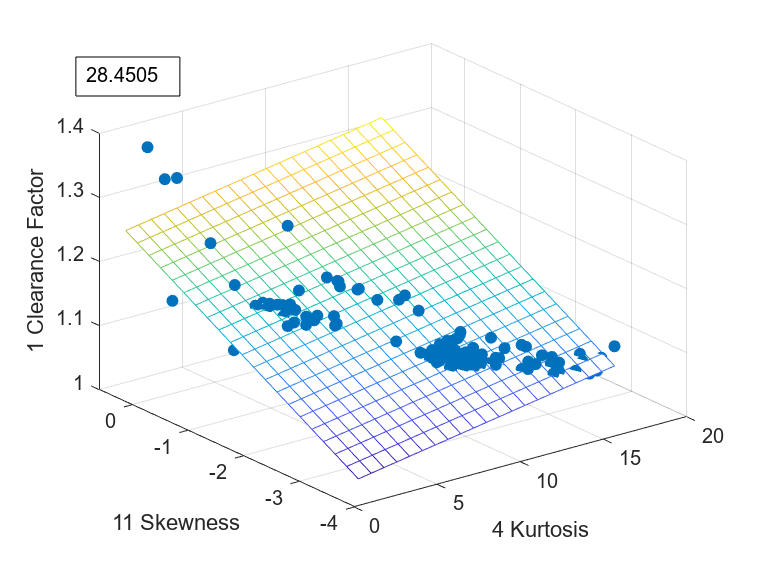

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 2

selectedFeature = 10;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures( ...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 6 = 0.95
Sig 5 Sig 7 = 1.00
     5     6     7    10    14
     5    10    14


figure(); hold on;
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

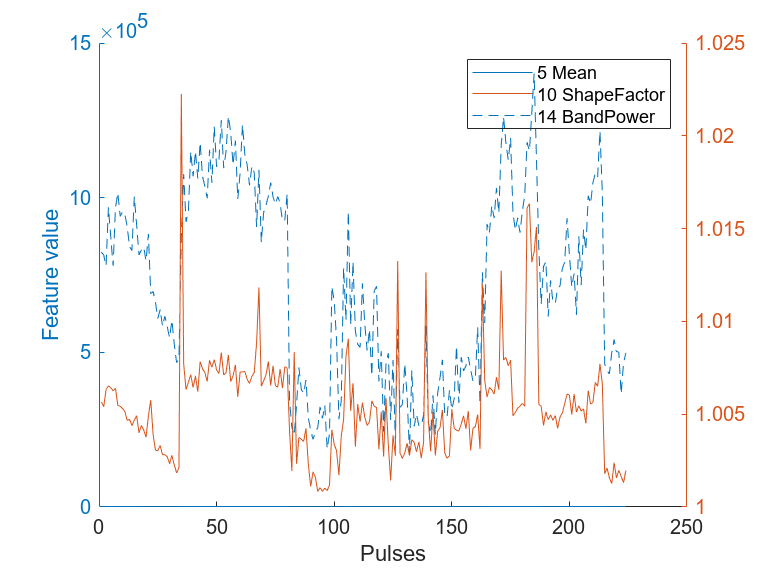

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
lgnd = legend(legendAxis, leg);
set(lgnd,'color','none');

xx = 1:numOfPulses;
plotyyy(xx', selectedFeatureData{1}, xx', selectedFeatureData{2}, xx', selectedFeatureData{3}, leg);
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

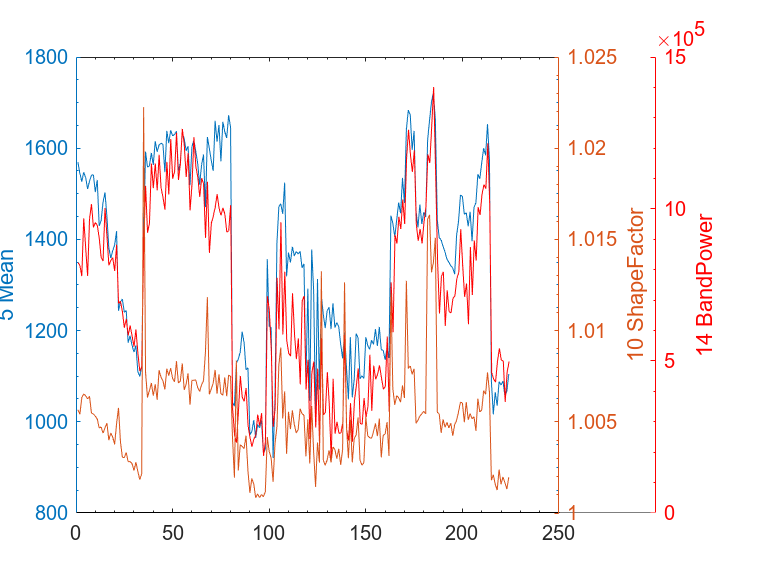

xlabel("Pulses");
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    export_fig(filename, '-eps', '-depsc');
end

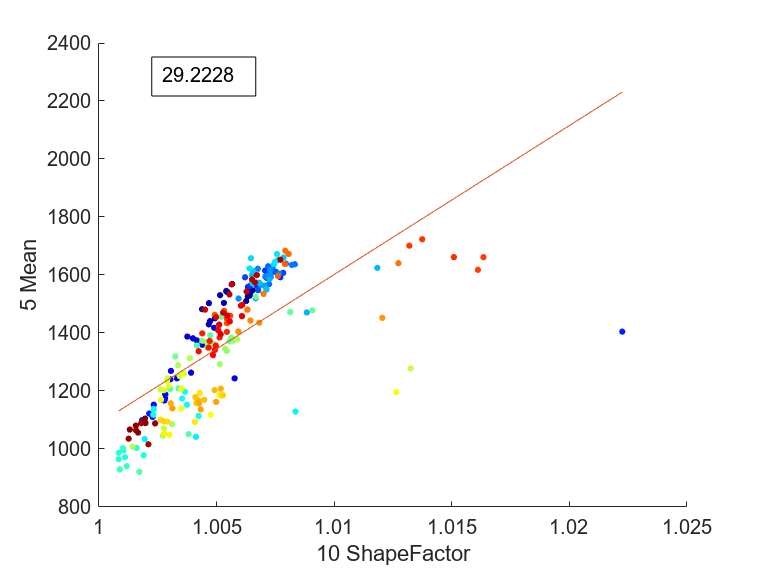

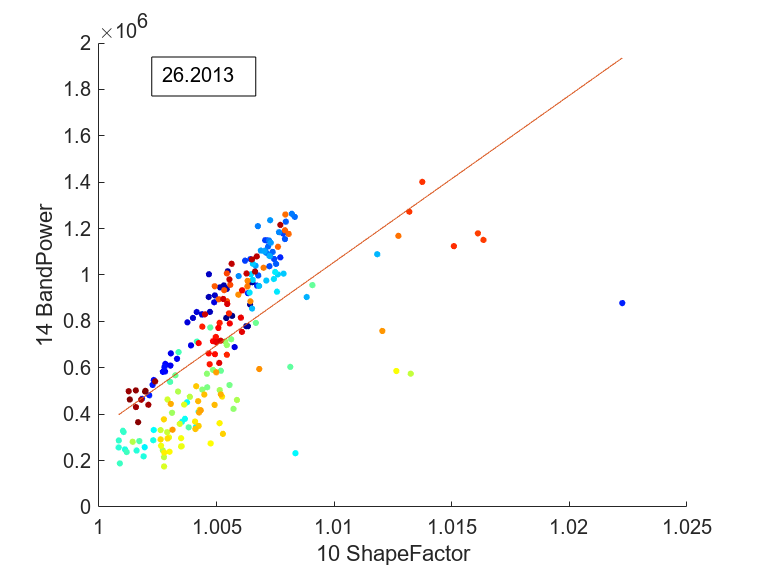

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

txtTitle = "21:12 Actual moment over Rolls [Nm]"

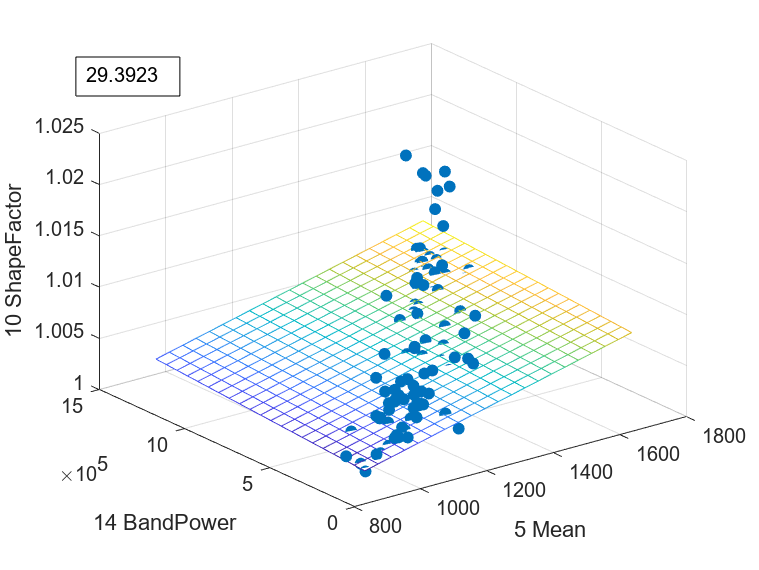

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 3

selectedFeature = 11;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures( ...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 1 Sig 2 = 0.99
Sig 1 Sig 3 = 1.00
     1     2     3    11
     1    11


disp(selectedFeatureArray);

     1    11


figure(); hold on;
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg);
set(lgnd,'color','none');

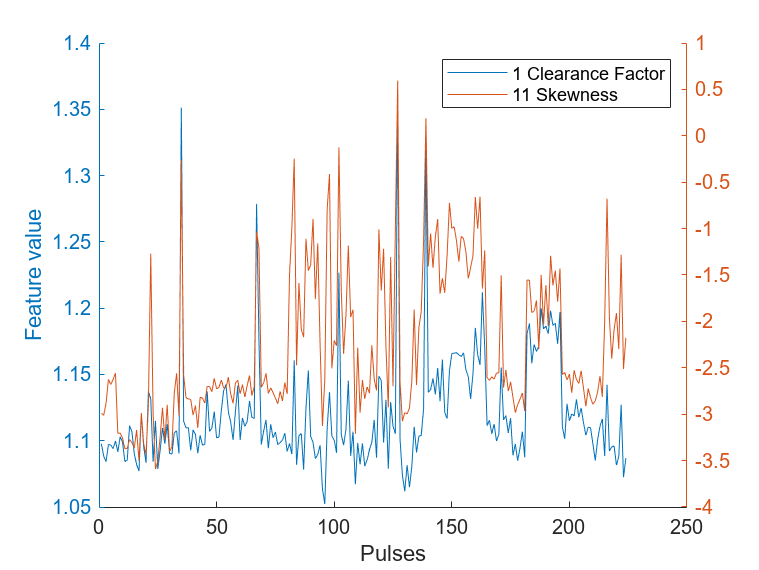

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff');    
    %export_fig(filename, '-eps', '-depsc');
end

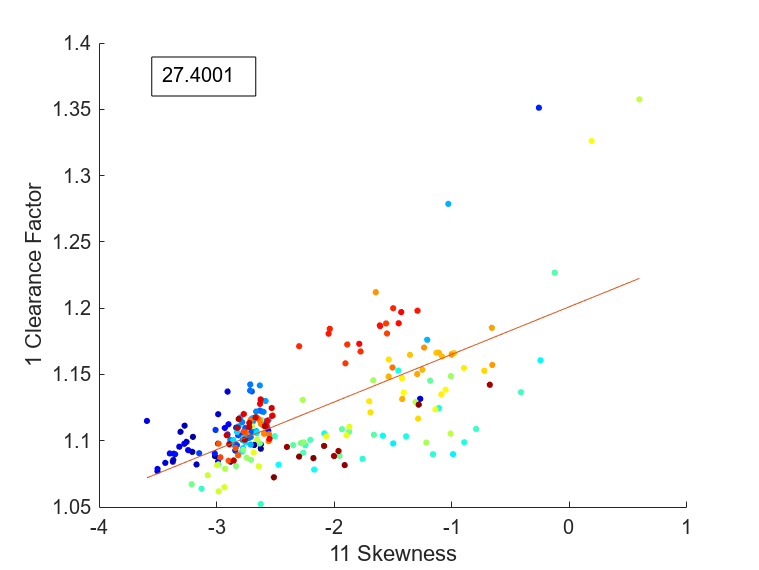

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 4

selectedFeature = 14;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures( ...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

    10    12    14
    10    12    14


figure(); hold on;
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

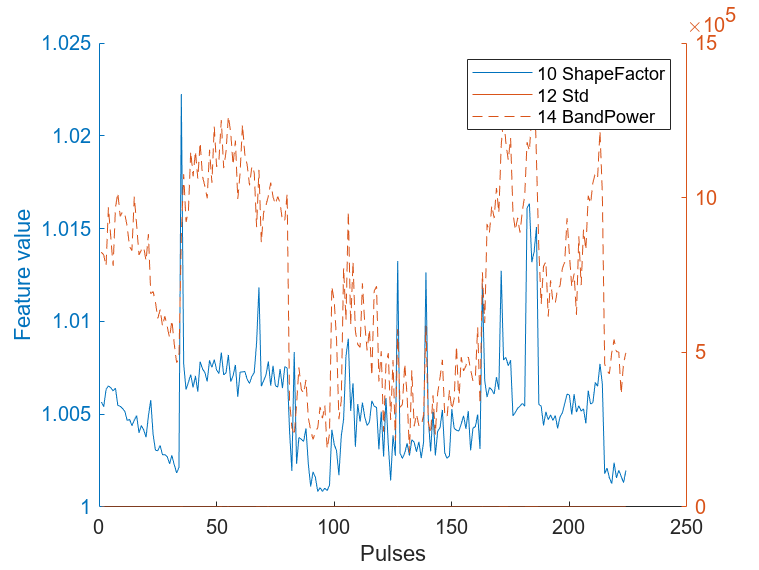

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2 3];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

set(lgnd,'color','none');

xx = 1:numOfPulses;
plotyyy(xx', selectedFeatureData{1}, xx', selectedFeatureData{2}, xx', selectedFeatureData{3}, leg);
sensorNames(selectedSignal)

ans = "21:12 Actual moment over Rolls [Nm]"

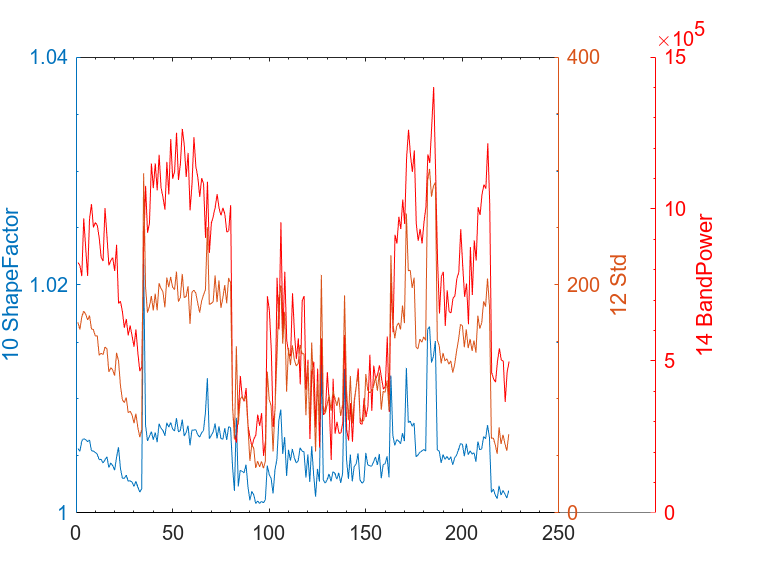

xlabel("Pulses");
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    export_fig(filename, '-eps', '-depsc');
end

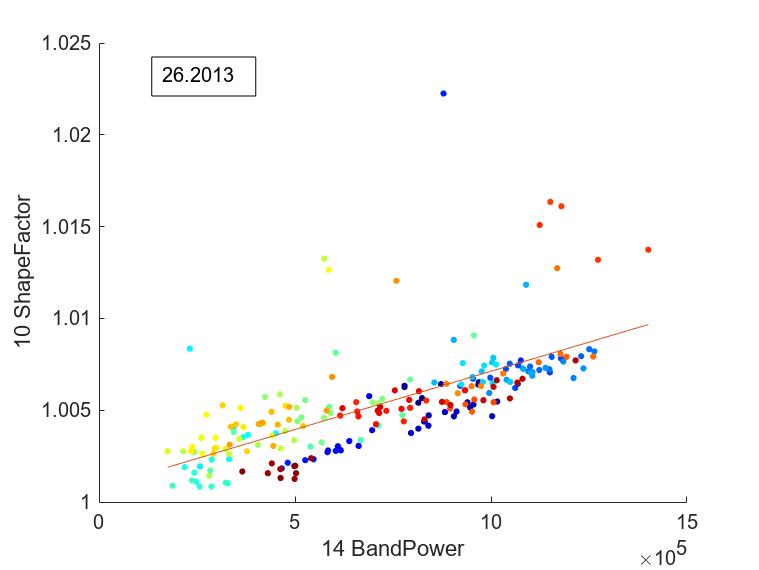

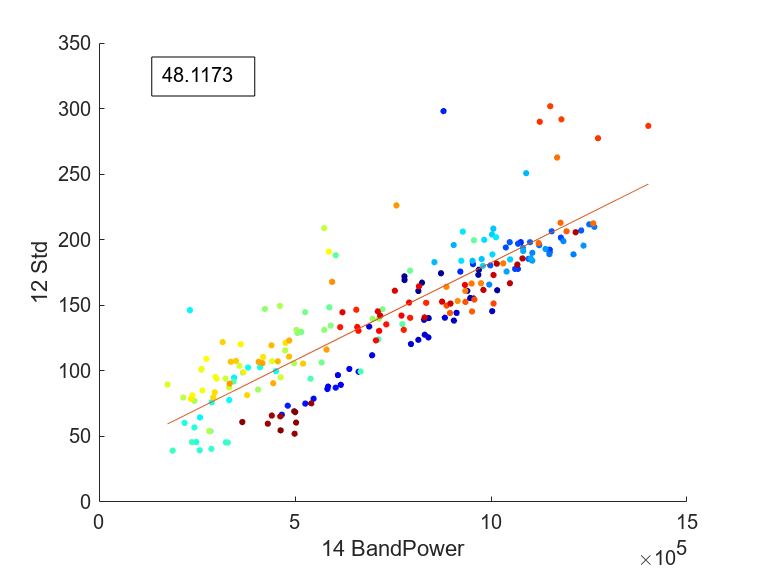

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

txtTitle = "21:12 Actual moment over Rolls [Nm]"

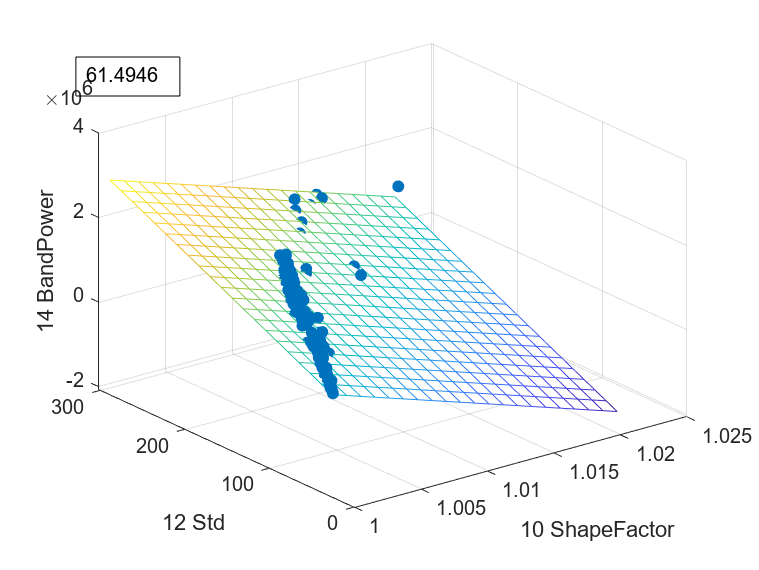

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

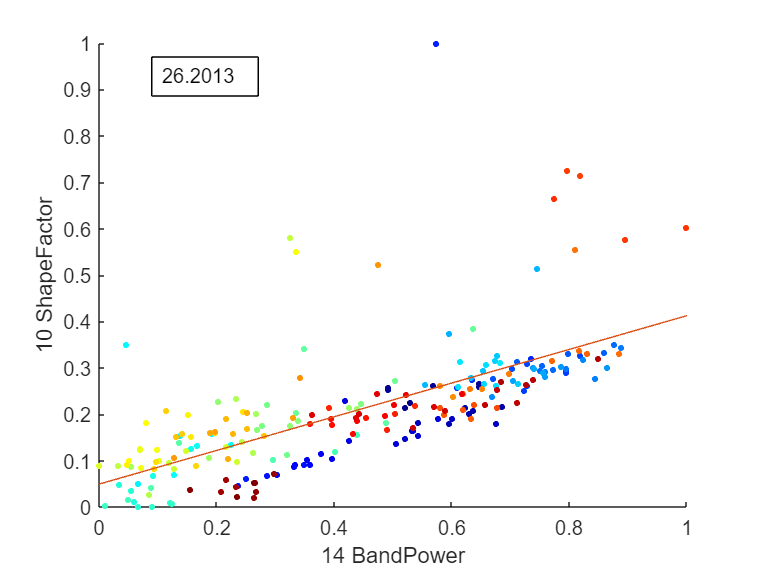

sigIndex = 3;
feat1 = 10;
feat2 = 14;
sig1 = fnNorm(featureArray(:, feat1, sigIndex));
sig2 = fnNorm(featureArray(:, feat2, sigIndex));
fnPlotModel(sig1, ...
            sig2, ...
            sensorNames(sigIndex), ...
            FeatureNames_Combined(feat1), ...
            FeatureNames_Combined(feat2));

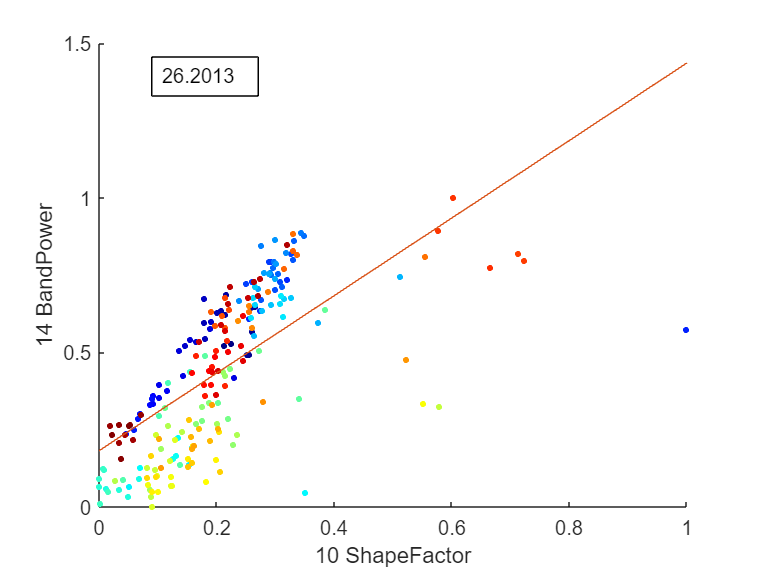

fnPlotModel(sig2, ...
            sig1, ...
            sensorNames(sigIndex), ...
            FeatureNames_Combined(feat2), ...
            FeatureNames_Combined(feat1));

function [signal] = fnNorm(signal)
    signalMin = min(signal);
    signal = signal - signalMin;
    signalMax = max(signal);
    signal = signal / signalMax;
end